# Sample 7-4

## 幾何学処理

有理数比の解像度変換

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Geometric image processing

Resizing w/ rational factor

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 補間率の設定

(Setting of upsampling factor)

- $M$: 補間率 (upsampling factor) 

% Upsampling factor
uFactor = 5;

### 間引き率の設定

(Setting of downsampling factor)

- $M$: 間引き率 (downsampling factor) 

% Downsampling factor
dFactor = 3;

### フィルタの設定

(Setting of filter)

平均フィルタのインパルス応答 (Impulse response of averaging filter)

        
$$h[n]=\left\{\begin{array}{ll} \frac{1}{M_\mathrm{d}} & 0\leq n\leq M_\mathrm{d}-1 \\ 0 & \mathrm{otherwise} \end{array}\right.$$


- $\{h[n]\}_n$: インパルス応答 (Impulse response)

% Impulse response of averaging filter
h = ones(1,dFactor)/dFactor;

線形補間フィルタのインパルス応答 (Impulse response of linear interpolation filter)

        
$$f[n]=\left\{\begin{array}{ll} \frac{1}{M_\mathrm{u}}(M_
\mathrm{u}-|n|) & -M_\mathrm{u}+1\leq n\leq M_\mathrm{u}-1 \\ 0 & \mathrm{otherwise} \end{array}\right.$$


ただし，非因果性に注意．(Note that the incausal property.)

- $\{f[n]\}_n$: インパルス応答 (Impulse response)

% Impulse response of interpolation filter
f = 1-abs(-(uFactor-1):(uFactor-1))/uFactor;

縦続フィルタのインパルス応答 (Impulse response of the cascade filter)

        
$$g[n]=h[n]\ast f[n]$$


% Impulse response of the combination
g = conv(h,f);

## フィルタ特性の表示

(Display of filter characteristics)

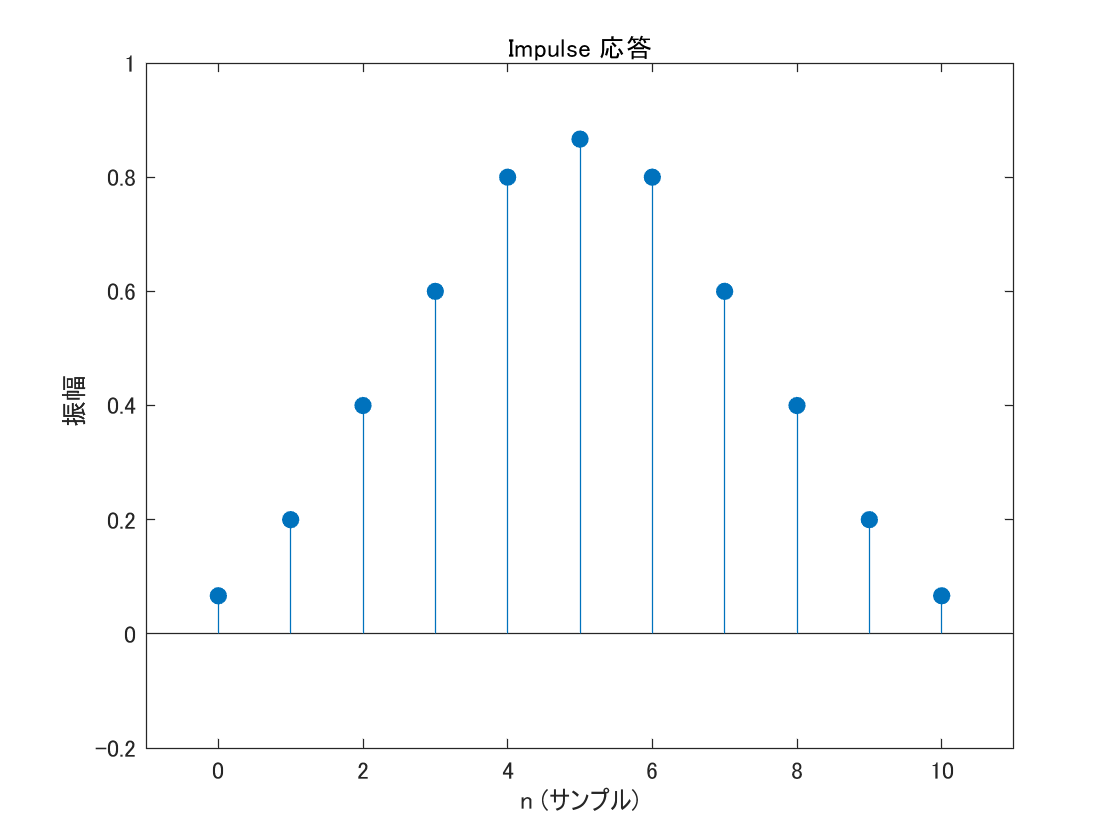

% Impulse response
figure(1)
impz(g)
ax = gca;
ax.XLim = [-1 length(g)];
ax.YLim = [-0.2 1];

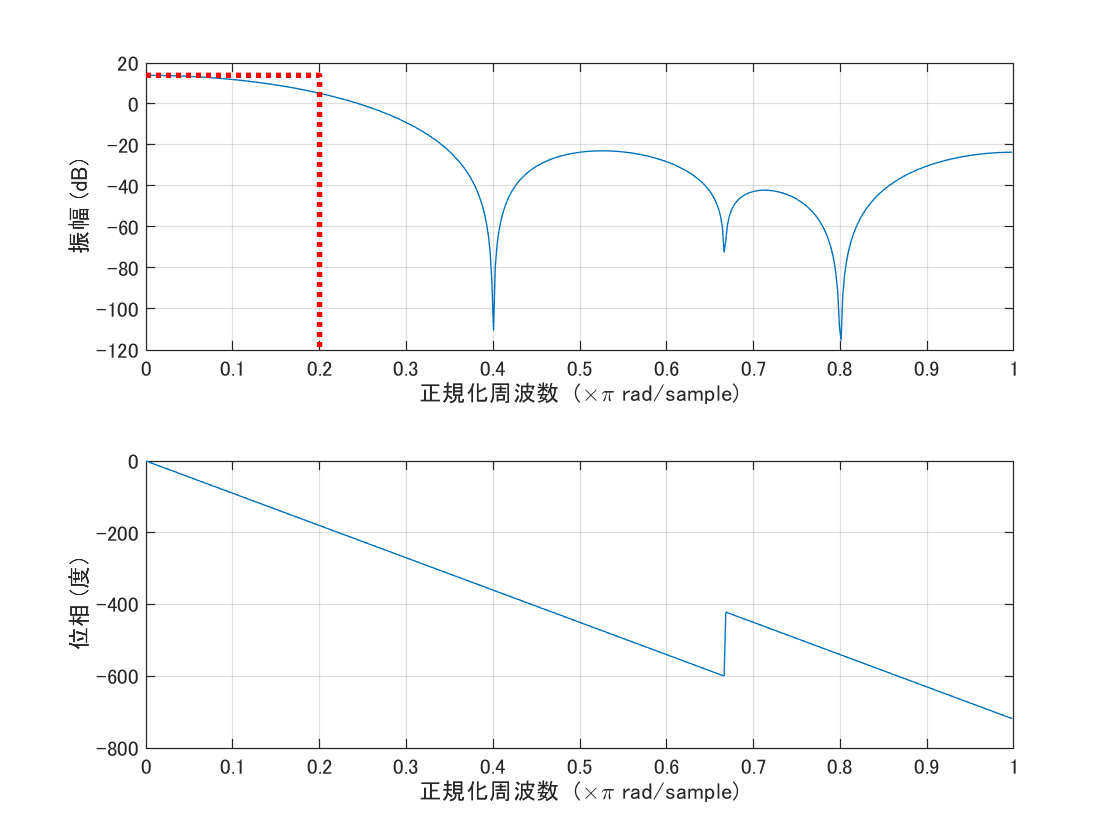


% Frequency response
figure(2)
freqz(g)
ax = gca;
hold on
line([0 min(1/uFactor,1/dFactor) min(1/uFactor,1/dFactor)],[20*log10(uFactor) 20*log10(uFactor) ax.YLim(1)],...
    'LineStyle',':','LineWidth',2,'Color','red');
hold off

### 画像への適用

(Application to images)

        
$$v[\mathbf{m}]=\sum_{\mathbf{\ell}\in\mathbb{Z}^2}u[\mathbf{M}_\mathrm{u}\mathbf{\ell}]g[\mathbf{M_\mathrm{d}m}-\mathbf{M}_\mathrm{u}\mathbf{\ell}]$$


ただし，(where)

        
$$g[\mathbf{n}]=h[\mathbf{n}]\ast f[\mathbf{n}]$$


        
$$h[\mathbf{n}]=\left\{\begin{array}{ll} \frac{1}{|\det\mathbf{M}_\mathbf{d}|} & \mathbf{n}\in \mathcal{N}(\mathbf{M}_\mathbf{d})\\ 0 & \mathrm{otherwise} \end{array}\right.$$


        
$$f[\mathbf{n}]=\left\{\begin{array}{ll} \mathrm{prod}\left(\mathbf{1}-\mathrm{abs}\left(\mathbf{M}_\mathbf{u}^{-1}\mathbf{n}\right) \right)& \mathbf{n}\in \{\mathbf{M}_\mathbf{u}\mathbf{x}\in\mathbb{Z}^2\ |\ \mathbf{x}\in(-1,1)^2\} \\ 0 & \mathrm{otherwise} \end{array}\right.$$


ただし，非因果性に注意．(Note that the incausal property.)

- $\{g[\mathbf{n}]\}_\mathbf{n}$: インパルス応答 (Impulse response)

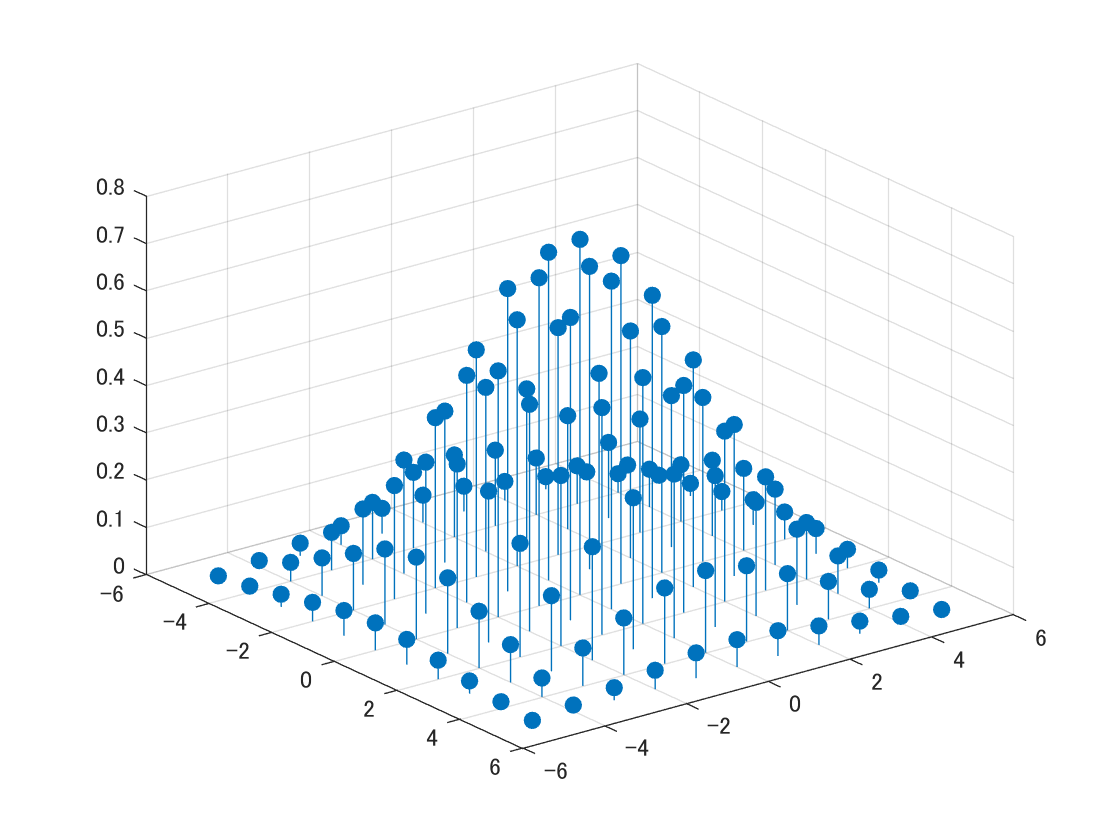

% Reading an image
u = imread('cameraman.tif');

% Generating the bilinear interpolation filter
[n1,n2] = ndgrid(-uFactor+1:uFactor-1);
f = (1-abs(n1)/uFactor).*(1-abs(n2)/uFactor);

% Generating the average filter
h = fspecial('average',dFactor);

% Combination of h and f
g = conv2(f,h);
[n1,n2] = ndgrid(-uFactor-floor(dFactor/2)+1:uFactor+floor(dFactor/2)-1);

% Impluse response 
figure(3)
stem3(n2,n1,g,'filled')
axis ij
ax = gca;
ax.XLim = ax.XLim + [-1 1];
ax.YLim = ax.YLim + [-1 1];

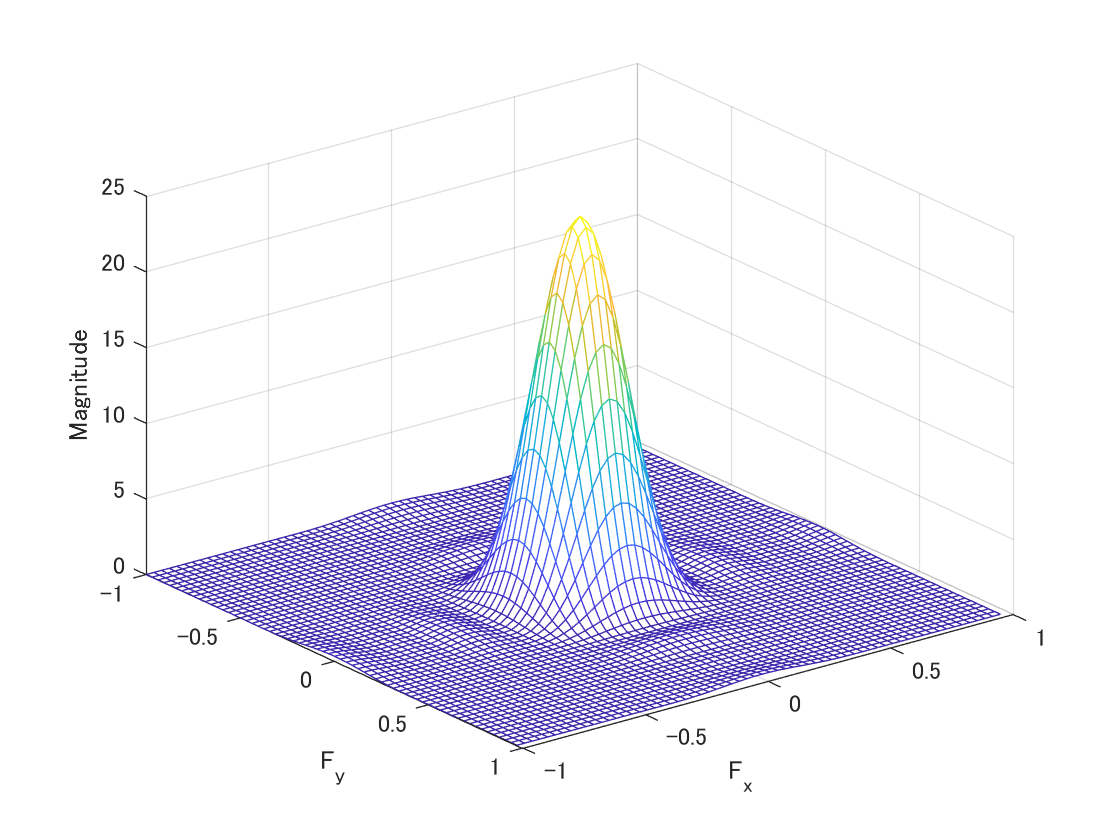


% Frequency response
figure(4)
freqz2(g)
axis ij

% Bivariate upsampling function
upsample2 = @(x,n) ...
    shiftdim(upsample(...
    shiftdim(upsample(x,...
    n(1)),1),...
    n(2)),1);

% Bivariate downsampling function
downsample2 = @(x,n) ...
    shiftdim(downsample(...
    shiftdim(downsample(x,...
    n(1)),1),...
    n(2)),1);

% Interpolation with upsampling and filtering
x = padarray(u,[1 1],'replicate','both');
w = imfilter(upsample2(x,uFactor*[1 1]),g,'conv');
s = ceil(uFactor/2);
y = w(s+1:s+uFactor*size(u,1),s+1:s+uFactor*size(u,2));
v = downsample2(y,dFactor*[1 1]);

### 画像表示

(Display image)

原画像 (Original)

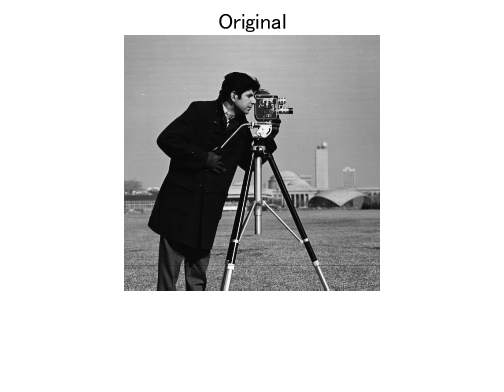

figure(5)
imshow(u)
title('Original')

結果画像 (Result)

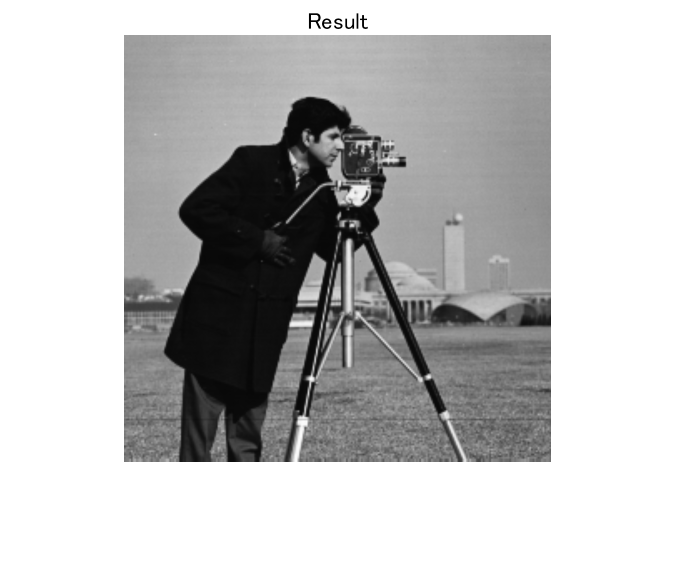

% Display result
figure(6)
imshow(v)
title('Result')

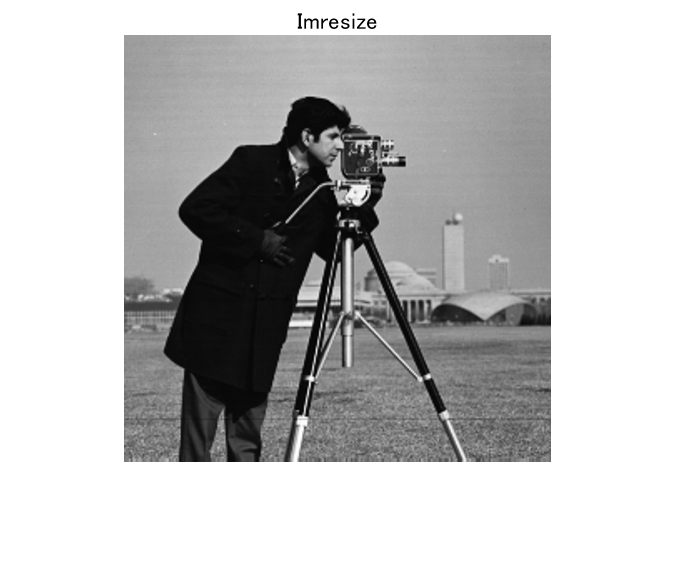

% Imresize
figure(7)
z = imresize(u,uFactor/dFactor);
imshow(z)
title('Imresize')

© Copyright, Shogo MURAMATSU, All rights reserved.